# Actividad Práctica N°1. Representación de sistemas y control PID.

## Caso de estudio 2. Sistema de tres variables de estado.

### Consigna

Dadas las ecuaciones del motor de corriente continua con torque de carga $T_L$ no nulo, con los parámetros:

- 
$$L_{\textrm{AA}} =366\;{10}^{-6}$$


- 
$$J=5\;{10}^{-9}$$


- 
$$R_A =55\ldotp 6$$


- 
$$B_m =0$$


- 
$$K_i =6\ldotp 49\;{10}^{-3}$$


- 
$$K_m =6\ldotp 53\;{10}^{-3}$$


Modelado por las siguientes ecuaciones diferenciales:

- 
$$\frac{{\textrm{di}}_a \;}{\textrm{dt}}=\frac{-R_A }{\;L_{\textrm{AA}} }*i_a -\frac{\;K_m }{\;L_{\textrm{AA}} }\omega_r +\frac{1\;}{L_{\textrm{AA}} }v_a$$


- 
$$\frac{d\omega_r }{\textrm{dt}}=\frac{K_i \;}{J}i_a -\frac{B_m \;}{J}\omega {\;}_r -\frac{1\;}{J}T_L$$


- 
$$\frac{d\Theta_t }{\textrm{dt}}=\omega_r$$


Implementar un algoritmo de simulación para inferir el comportamiento de las variables interés  mediante integración Euler con $\Delta t={10}^{-7}$segundos para:

- Obtener el torque máximo que puede soportar el motor modelado mediante las ecuaciones diferenciales anteriores cuando se lo alimenta con $12V$, graficando para $5$ segundos de tiempo la velocidad angular y la corriente $i_a$.

- Mostrar simulaciones de 5 segundos que permitan observar la corriente $i_a$ en todo momento y establecer su valor máximo como para dimensionar dispositivos electrónicos.

- A partir de las curvas de mediciones de las variables graficadas, se requiere obtener el modelo del sistema considerando como entrada un escalón de $12V$, como salida a la velocidad angular, y a partir de $0\ldotp 1$ segundo se aplica un $T_L$ aproximado de $7\ldotp 5\;{10}^{-2} \;\textrm{Nm}$. En el archivo Curvas_Medidas_Motor.xls están las mediciones, en la primer hoja los valores y en la segunda los nombres. Se requiere obtener el modelo dinámico, para establecer las constantes de la corriente.

- Implementar un PID en tiempo discreto para que el ángulo del motor permanezca en una referencia de $1\;\textrm{rad}$. (Tip: a partir de $K_P =0\ldotp 1;K_i =0\ldotp 01;K_D =5$).

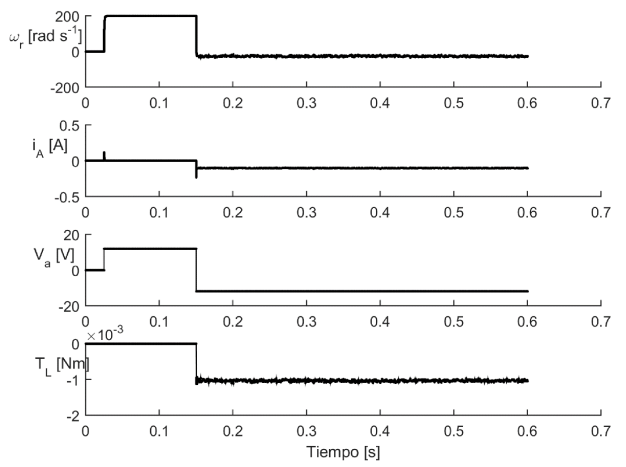

### Resolución

En primera instancia se integran las dos primeras ecuaciones diferenciales haciendo uso del método de Integración de Euler, con el paso fijado en la consigna del ejercicio.

Primero se pasiva la entrada que responde al torque del motor, para integrar las ecuaciones de velocidad angular y corriente en función de la entrada de tensión. Se aplica el teorema de superposición.

T = 0.6;
deltaT = 1e-7;
Kmax = T/deltaT;
t = linspace(0,T,Kmax);

Laa = 366e-6;
J = 5e-9;
Ra = 55.6;
Bm = 0;
Ki = 6.49e-3;
Km = 6.53e-3;

Vin = 12;
iaP = 0;
wrP = 0;
Ia = zeros(1, Kmax);
Wr = zeros(1, Kmax);
u = linspace(0, 0, Kmax);
Ia(1) = 0;
Wr(1) = 0;
u(1) = Vin;

A = [-Ra/Laa -Km/Laa; Ki/J -Bm/J];
B = [1/Laa; 0];
C1 = [1 0];
C2 = [0 1];

Ial(1) = 0;
Wrl(1) = 0;
x = [Ia(1) Wr(1)]';
Xop = [0 0]';

ii = 0;
for i = 1:(Kmax-1)
    ii = ii+deltaT;
    if(ii>=0 && ii<0.025)
        Vin = 0;
    end
    if(ii>=0.025 && ii<0.15)
        Vin = 12;
    end
    if(ii>=0.15)
        Vin = -12;
    end
    u(i) = Vin;
    iaP = -(Ra/Laa)*Ia(i)-(Km/Laa)*Wr(i)+(1/Laa)*u(i);
    wrP = (Ki/J)*Ia(i)-(Bm/J)*Wr(i);
    xP = A*(x-Xop)+B*u(i);
    x = x+xP*deltaT;
    Y1 = C1*x;
    Y2 = C2*x;
    Ial(i+1) = x(1);
    Wrl(i+1) = x(2);
end

A continuación, se grafican las dos salidas del sistema planteado para una entrada de tensión que inicia en $0V$, luego, al cabo de $0\ldotp 025\;\textrm{seg}$ comienza a valer $12V$, para luego, a los $0\ldotp 125\;\textrm{seg}$ cambiar su signo, pasando a valer $-12V$.

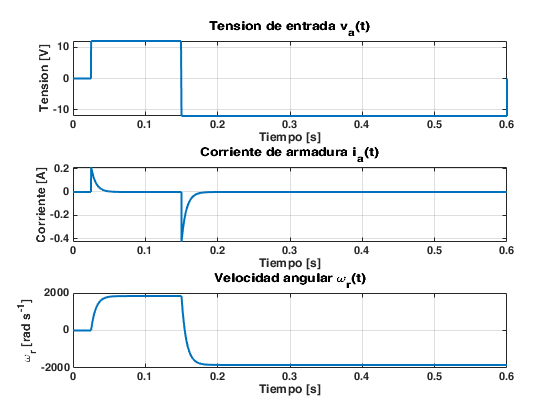

subplot(3,1,1);
plot(t,u,'LineWidth',1.5);
title('Tension de entrada v_a(t)');
xlabel('Tiempo [s]');
ylabel('Tension [V]');
grid;
subplot(3,1,2);
plot(t,Ial,'LineWidth',1.5); 
title('Corriente de armadura i_a(t)');
xlabel('Tiempo [s]');
ylabel('Corriente [A]')
grid;
subplot(3,1,3);
plot(t,Wrl,'LineWidth',1.5); 
title('Velocidad angular \omega_r(t)');
xlabel('Tiempo [s]');
ylabel('\omega_r [rad s^{-1}]')
grid;

Las gráficas anteriores son para simplemente comparar resultados con las gráficas brindadas por la consigna. Ahora, para continuar con lo solicitado, se ingresará el escalón de tensión de $12\;V$ y se simulará el sistema durante $5\;\textrm{seg}$.

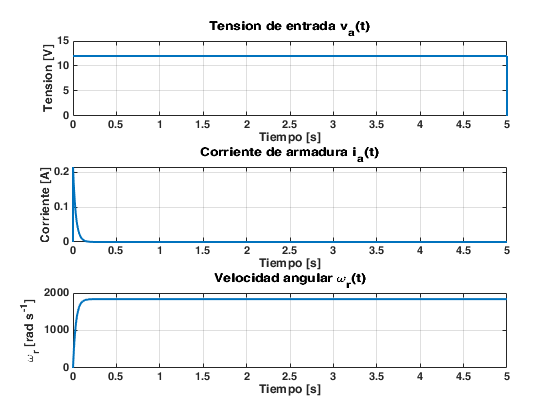

T = 5;
deltaT = 1e-7;
Kmax = 10000000;
t = linspace(0,T,Kmax);

Laa = 366e-6;
J = 5e-9;
Ra = 55.6;
Bm = 0;
Ki = 6.49e-3;
Km = 6.53e-3;

Vin = 12;
iaP = 0;
wrP = 0;
Ia = zeros(1, Kmax);
Wr = zeros(1, Kmax);
u = linspace(0, 0, Kmax);
Ia(1) = 0;
Wr(1) = 0;
u(1) = Vin;

A = [-Ra/Laa -Km/Laa; Ki/J -Bm/J];
B = [1/Laa; 0];
C1 = [1 0];
C2 = [0 1];

Ial(1) = 0;
Wrl(1) = 0;
x = [Ia(1) Wr(1)]';
Xop = [0 0]';

ii = 0;
for i = 1:(Kmax-1)
    ii = ii+deltaT;
    u(i) = Vin;
    iaP = -(Ra/Laa)*Ia(i)-(Km/Laa)*Wr(i)+(1/Laa)*u(i);
    wrP = (Ki/J)*Ia(i)-(Bm/J)*Wr(i);
    xP = A*(x-Xop)+B*u(i);
    x = x+xP*deltaT;
    Y1 = C1*x;
    Y2 = C2*x;
    Ial(i+1) = x(1);
    Wrl(i+1) = x(2);
end

subplot(3,1,1);
plot(t,u,'LineWidth',1.5);
title('Tension de entrada v_a(t)');
xlabel('Tiempo [s]');
ylabel('Tension [V]');
grid;
figure(1)
subplot(3,1,2);
plot(t,Ial,'LineWidth',1.5); 
title('Corriente de armadura i_a(t)');
xlabel('Tiempo [s]');
ylabel('Corriente [A]')
grid;
subplot(3,1,3);
plot(t,Wrl,'LineWidth',1.5); 
title('Velocidad angular \omega_r(t)');
xlabel('Tiempo [s]');
ylabel('\omega_r [rad s^{-1}]')
grid;

El problema pide mostrar simulaciones de $5\;\textrm{seg}$ que permitan observar la corriente $i_a$ en todo momento y establecer su valor pico para poder dimensionar dispositivos electrónicos. El gráfico de la corriente puede verse en la figura anterior. A continuación se muestra el pico de esa corriente.

disp('El pico de corriente es de:')

El pico de corriente es de:


iMax = max(Ial)

iMax = 0.2146

Ahora, para obtener el torque máximo que puede soportar el motor cuando se le aplica una entrada de tensión de $12V$, se puede utilizar la ecuación que modela el torque. Es decir:


$$T=K_m i_a$$


Siendo que se conoce el máximo de la corriente para la entrada definida, simplemente restaría evaluar la expresión anterior para las condiciones dadas:

Tmax = Km*iMax

Tmax = 0.0014

Finalmente, el torque máximo que puede soportar el motor para estas condiciones de funcionamiento es de $1\ldotp 4\;{10}^{-3} \;\textrm{Nm}$.

Ahora, para poder implementar el modelado de un sistema MIMO, es decir, múltiples entradas y múltiples salidas, se transforma el sistema de ecuaciones diferenciales al dominio de Laplace, para poder así despejar lo necesario. Se utilizará el paquete simbólico para esta tarea.


$${\textrm{sI}}_a \left(s\right)=-\frac{R_A \;}{L_{\textrm{AA}} }I_a \left(s\right)-\frac{K_m \;}{L_{\textrm{AA}} }\Omega {\;}_r \left(s\right)+\frac{1\;}{L_{\textrm{AA}} }V_a \left(s\right)$$



$$s\Omega {\;}_r \left(s\right)=\frac{K_i \;}{J}I_a \left(s\right)-\frac{B_m \;}{J}\Omega {\;}_r \left(s\right)-\frac{1\;}{J}T_L \left(s\right)$$



$$s\Theta {\;}_t =\Omega {\;}_r \left(s\right)$$


syms s I_a R_A L_AA K_m Omega_r V_a K_i J B_m Theta_t real;
eq1 = s*I_a == -(R_A/L_AA)*I_a-(K_m/L_AA)*Omega_r+(1/L_AA)*V_a

$$eq1 = I_{a}\,s=\frac{V_{a}}{L_{\mathrm{AA}}}-\frac{K_{m}\,\Omega_{r}}{L_{\mathrm{AA}}}-\frac{I_{a}\,R_{A}}{L_{\mathrm{AA}}}$$

eq2 = s*Omega_r == (K_i/J)*I_a-(B_m/J)*Omega_r

$$eq2 = \Omega_{r}\,s=\frac{I_{a}\,K_{i}}{J}-\frac{B_{m}\,\Omega_{r}}{J}$$

Se obtienen las funciones de transferencia que relacionan la velocidad angular y la corriente con la tensión de entrada, para ello se pasiva la entrada de $T_L$.

Omega_r = solve(eq2,Omega_r)

$$Omega\_r = \frac{I_{a}\,K_{i}}{B_{m}+J\,s}$$

eq1 = eval(eq1)

$$eq1 = I_{a}\,s=\frac{V_{a}}{L_{\mathrm{AA}}}-\frac{I_{a}\,R_{A}}{L_{\mathrm{AA}}}-\frac{I_{a}\,K_{i}\,K_{m}}{L_{\mathrm{AA}}\,\left(B_{m}+J\,s\right)}$$

Ia_Va = collect(simplify(solve(eq1,I_a)/V_a))

$$Ia\_Va = \frac{J\,s+B_{m}}{\left(J\,L_{\mathrm{AA}}\right)\,s^{2}+\left(B_{m}\,L_{\mathrm{AA}}+J\,R_{A}\right)\,s+B_{m}\,R_{A}+K_{i}\,K_{m}}$$

syms I_a Omega_r real;
eq1 = s*I_a == -(R_A/L_AA)*I_a-(K_m/L_AA)*Omega_r+(1/L_AA)*V_a;
eq2 = s*Omega_r == (K_i/J)*I_a-(B_m/J)*Omega_r;
I_a = solve(eq2,I_a)

$$I\_a = \frac{B_{m}\,\Omega_{r}+J\,\Omega_{r}\,s}{K_{i}}$$

eq1 = collect(eval(eq1))

$$eq1 = \frac{J\,\Omega_{r}}{K_{i}}\,s^{2}+\frac{B_{m}\,\Omega_{r}}{K_{i}}\,s=\left(-\frac{J\,\Omega_{r}\,R_{A}}{K_{i}\,L_{\mathrm{AA}}}\right)\,s+\frac{V_{a}}{L_{\mathrm{AA}}}-\frac{K_{m}\,\Omega_{r}}{L_{\mathrm{AA}}}-\frac{B_{m}\,\Omega_{r}\,R_{A}}{K_{i}\,L_{\mathrm{AA}}}$$

Omegar_Va = collect(simplify(solve(eq1,Omega_r)/V_a))

$$Omegar\_Va = \frac{K_{i}}{\left(J\,L_{\mathrm{AA}}\right)\,s^{2}+\left(B_{m}\,L_{\mathrm{AA}}+J\,R_{A}\right)\,s+B_{m}\,R_{A}+K_{i}\,K_{m}}$$

Siendo que la posición angular es definida como la integral de la velocidad angular, para obtener la función de transferencia de la misma basta simplemente con la aplicación de un integrador a la última función de transferencia obtenida. De esta forma se obtiene:

Thetar_Va = collect(simplify(Omegar_Va/s))

$$Thetar\_Va = \frac{K_{i}}{\left(J\,L_{\mathrm{AA}}\right)\,s^{3}+\left(B_{m}\,L_{\mathrm{AA}}+J\,R_{A}\right)\,s^{2}+\left(B_{m}\,R_{A}+K_{i}\,K_{m}\right)\,s}$$

Ahora, para las funciones de transferencia que involucran al torque de carga como variable de entrada:

syms s I_a R_A L_AA K_m Omega_r K_i J B_m T_L Theta_t real;
eq1 = s*I_a == -(R_A/L_AA)*I_a-(K_m/L_AA)*Omega_r

$$eq1 = I_{a}\,s=-\frac{K_{m}\,\Omega_{r}}{L_{\mathrm{AA}}}-\frac{I_{a}\,R_{A}}{L_{\mathrm{AA}}}$$

eq2 = s*Omega_r == (K_i/J)*I_a-(B_m/J)*Omega_r-(1/J)*T_L

$$eq2 = \Omega_{r}\,s=\frac{I_{a}\,K_{i}}{J}-\frac{B_{m}\,\Omega_{r}}{J}-\frac{T_{L}}{J}$$

Omega_r = solve(eq1,Omega_r);
eq2 = eval(eq2);
I_a = solve(eq2,I_a)

$$I\_a = \frac{T_{L}}{J\,\left(\frac{K_{i}}{J}+\frac{s\,\left(R_{A}+L_{\mathrm{AA}}\,s\right)}{K_{m}}+\frac{B_{m}\,\left(R_{A}+L_{\mathrm{AA}}\,s\right)}{J\,K_{m}}\right)}$$

Ia_TL = collect(simplify(I_a/T_L))

$$Ia\_TL = \frac{K_{m}}{\left(J\,L_{\mathrm{AA}}\right)\,s^{2}+\left(B_{m}\,L_{\mathrm{AA}}+J\,R_{A}\right)\,s+B_{m}\,R_{A}+K_{i}\,K_{m}}$$

syms I_a Omega_r real;
eq1 = s*I_a == -(R_A/L_AA)*I_a-(K_m/L_AA)*Omega_r;
eq2 = s*Omega_r == (K_i/J)*I_a-(B_m/J)*Omega_r-(1/J)*T_L;
I_a = solve(eq1,I_a);
eq2 = eval(eq2);
Omega_r = solve(eq2,Omega_r);
Omegar_TL = collect(simplify(Omega_r/T_L))

$$Omegar\_TL = \frac{\left(-L_{\mathrm{AA}}\right)\,s-R_{A}}{\left(J\,L_{\mathrm{AA}}\right)\,s^{2}+\left(B_{m}\,L_{\mathrm{AA}}+J\,R_{A}\right)\,s+B_{m}\,R_{A}+K_{i}\,K_{m}}$$

Thetar_TL = collect(simplify(Omegar_TL/s))

$$Thetar\_TL = \frac{\left(-L_{\mathrm{AA}}\right)\,s-R_{A}}{\left(J\,L_{\mathrm{AA}}\right)\,s^{3}+\left(B_{m}\,L_{\mathrm{AA}}+J\,R_{A}\right)\,s^{2}+\left(B_{m}\,R_{A}+K_{i}\,K_{m}\right)\,s}$$

Anteriormente se obtuvieron las diferentes funciones de transferencia del sistema. Con ello, es posible plantear una matriz para un sistema MIMO, en donde cada posición de la misma relacione una entrada con una salida del sistema. Las columnas representan las entradas y las filas las salidas. Se puede resumir entonces el sistema en:

[Ia_Va Ia_TL; Omegar_Va Omegar_TL; Thetar_Va Thetar_TL]

$$ans = \begin{array}{l} \left(\begin{array}{cc} \frac{J\,s+B_{m}}{\sigma_{1}} & \frac{K_{m}}{\sigma_{1}}\\ \frac{K_{i}}{\sigma_{1}} & \frac{\left(-L_{\mathrm{AA}}\right)\,s-R_{A}}{\sigma_{1}}\\ \frac{K_{i}}{\sigma_{2}} & \frac{\left(-L_{\mathrm{AA}}\right)\,s-R_{A}}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(J\,L_{\mathrm{AA}}\right)\,s^{2}+\left(B_{m}\,L_{\mathrm{AA}}+J\,R_{A}\right)\,s+B_{m}\,R_{A}+K_{i}\,K_{m}\\ \sigma_{2}=\left(J\,L_{\mathrm{AA}}\right)\,s^{3}+\left(B_{m}\,L_{\mathrm{AA}}+J\,R_{A}\right)\,s^{2}+\left(B_{m}\,R_{A}+K_{i}\,K_{m}\right)\,s \end{array}$$

Es importante notar que las ecuaciones carácterísticas son exactamente iguales para las primeras 4 funciones de transferencia, lo que corrobora el modelado. Y luego, las funciones que relacionan la salida de $\Theta {\;}_t$ tienen la misma ecuación característica también, que resulta del producto entre las primeras ecuaciones carácterísticas por la variable de Laplace $s$.

A continuación, se graficarán las mediciones presentes en el archivo de Excel:

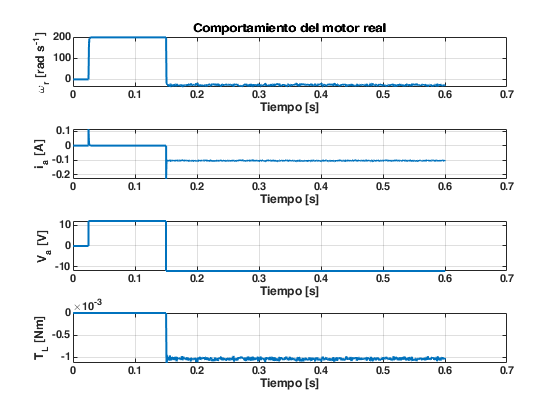

filename = 'curvasMotor.xlsx';
sheet = 1;
t = xlsread(filename,sheet,'A1:A31054');
w = xlsread(filename,sheet,'B1:B31054');
i = xlsread(filename,sheet,'C1:C31054');
v = xlsread(filename,sheet,'D1:D31054');
T = xlsread(filename,sheet,'E1:E31054');

subplot(4,1,1);
plot(t,w,'LineWidth',1.5);
ylabel('\omega_r [rad s^{-1}]');
xlabel('Tiempo [s]');
title('Comportamiento del motor real')
grid;
subplot(4,1,2);
plot(t,i,'LineWidth',1.5);
ylabel('i_a [A]');
xlabel('Tiempo [s]');
grid;
subplot(4,1,3);
plot(t,v,'LineWidth',1.5);
ylabel('V_a [V]');
xlabel('Tiempo [s]');
grid;
subplot(4,1,4);
plot(t,T,'LineWidth',1.5);
ylabel('T_L [Nm]');
xlabel('Tiempo [s]');
grid;

Para reconocer la función de transferencia que relaciona la velocidad angular con la tensión de entrada junto con sus constantes escalares, se utiliza el método de Chen. Para ello, se define $t_1 =1\ldotp 9\;{10}^{-6} \;\textrm{seg}$. Se tienen así entonces:

- 
$$y\left(t_1 \right)=0\ldotp 13231206$$


- 
$$y\left(2t_1 \right)=0\ldotp 51227978$$


- 
$$y\left(3t_1 \right)=1\ldotp 0610847$$


- 
$$K=198$$


t1 = 1.9e-6;
y1 = 0.13231206;
y2 = 0.51227978;
y3 = 1.0610847;
K = 198;

k1 = (y1/K)-1

k1 = -0.9993

k2 = (y2/K)-1

k2 = -0.9974

k3 = (y3/K)-1

k3 = -0.9946

b = 4*k1^3*k3-3*k1^2*k2^2-4*k2^3+k3^2+6*k1*k2*k3

b = 1.4864e-07

alpha1 = (k1*k2+k3-sqrt(b))/(2*(k1^2+k2))

alpha1 = 0.6872

alpha2 = (k1*k2+k3+sqrt(b))/(2*(k1^2+k2))

alpha2 = 0.9953

beta = (2*k1^3+3*k1*k2+k3-sqrt(b))/sqrt(b)

beta = -2.0260

T1 = -t1/(log(alpha1))

T1 = 5.0649e-06

T2 = -t1/(log(alpha2))

T2 = 4.0530e-04

T3 = beta*(T1-T2)+T1

T3 = 8.1595e-04

s = tf('s');
OmegaVa = minreal((K)/((T1*s+1)*(T2*s+1)))/12

OmegaVa =
 
             9.645e10
  ------------------------------
  12 s^2 + 2.399e06 s + 5.846e09
 
Continuous-time transfer function.



zpk(OmegaVa)

ans =
 
       8.0378e+09
  ---------------------
  (s+1.974e05) (s+2467)
 
Continuous-time zero/pole/gain model.



Se repite el procedimiento para hallar la función de transferencia que relaciona la velocidad angular con el torque.

Se plantea que la ganancia del sistema es:

- 
$$K=171$$


- 
$$t_1 =1\mu \;\mathrm{seg}$$


- 
$$y\left(t_1 \right)=-0\ldotp 11090132$$


- 
$$y\left(2t_1 \right)=-0\ldotp 18112165$$


- 
$$y\left(3t_1 \right)=-0\ldotp 2504948$$


Se reacomodan los valores anteriores, de forma de obtener una progresión positiva, se los declara a continuación:

t1 = 1e-6;
y1 = 171.4+0.11090132;
y2 = 171.4+0.18112165;
y3 = 171.4+0.2504948;
K = (171.4/1.03e-3);
k1 = (y1/K)-1

k1 = -0.9990

k2 = (y2/K)-1

k2 = -0.9990

k3 = (y3/K)-1

k3 = -0.9990

b = 4*k1^3*k3-3*k1^2*k2^2-4*k2^3+k3^2+6*k1*k2*k3

b = 1.0592e-06

alpha1 = (k1*k2+k3-sqrt(b))/(2*(k1^2+k2))

alpha1 = 1.0000

alpha2 = (k1*k2+k3+sqrt(b))/(2*(k1^2+k2))

alpha2 = 4.9411e-06

beta = (2*k1^3+3*k1*k2+k3-sqrt(b))/(sqrt(b))

beta = -0.0021

T1 = -t1/(log(alpha1))

T1 = 2.3977

T2 = -t1/(log(alpha2))

T2 = 8.1847e-08

T3 = beta*(T1-T2)+T1

T3 = 2.3928

s = tf('s');
OmegaT = minreal((K)*(T3*s+1)/((T1*s+1)*(T2*s+1)*(-1)))

OmegaT =
 
    -2.029e12 s - 8.479e11
  ---------------------------
  s^2 + 1.222e07 s + 5.096e06
 
Continuous-time transfer function.



zpk(OmegaT)

ans =
 
   -2.029e12 (s+0.4179)
  -----------------------
  (s+1.222e07) (s+0.4171)
 
Continuous-time zero/pole/gain model.



Ahora, con todas las funciones declaradas, se procede a obtener las respuestas del sistema ante las entradas haciendo uso de un bucle for y un paso (step) de $h=1e-7$ tal como lo solicita la consigna.

h = 1e-7;
simTime = 0.6004;
t = 0:h:(simTime-h);

Ahora, se crean 2 bucles en donde cada uno representa una entrada al sistema.

va = zeros(1,round(simTime/h));
tL = zeros(1,round(simTime/h));
timeInstants = round(simTime/h)

timeInstants = 6004000

for i = round(0.0250001/h):1:timeInstants
    if(i <= round(0.1501/h))
        va(1,i) = 12;
    else 
        va(1,i) = -12;
    end
end
[wv, twv] = lsim(OmegaVa,va(1,:),t);
for i = round(0.1503883/h):1:timeInstants
    tL(1,i) = -1.04e-3;
end
[wt, twt] = lsim(OmegaT,tL(1,:),t);

Ahora, luego de realizar las simulaciones lineales, se procede a sumar las señales obtenidas gracias a la aplicación del teorema de la superposición.

omega = wv+wt;

Y se grafica el resultado obtenido.

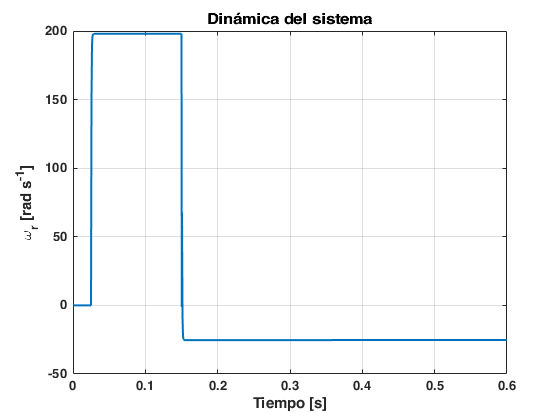

plot(t,omega,'LineWidth',1.5)
title('Dinámica del sistema')
ylabel('\omega_r [rad s^{-1}]');
xlabel('Tiempo [s]');
xlim([0 0.6])
grid

Para continuar con la obtención de las funciones de transferencia que modelan el comportamiento dinámico del motor se procede a reescribir las funciones de transferencia según la ganancia que se conoce que tiene la función que relaciona la velocidad angular con la tensión de entrada. Para ello, se plantea que, la entrada de tensión que se le aplica al sistema es de 12V, y se establece en el valor:

dcgain(12*OmegaVa)

ans = 198

Lo que significa que el sistema gana para una entrada unitaria:

dcgain(OmegaVa)

ans = 16.5000

Entonces se reescribe la función de transferencia obtenida de forma de tener en el numerador la ganancia $16\ldotp 5$.

[num,den] = tfdata(OmegaVa)

num = 1×1 cell array
    {[0 0 9.6453e+10]}


den = 1×1 cell array
    {[12 2.3988e+06 5.8456e+09]}


Es decir, que se deben dividir ambos polinomios por el valor de: $\frac{9\ldotp 6453\mathrm{e10}}{16\ldotp 5}$

num = [16.5]

num = 16.5000

converFactor = 9.6453e10/16.5;
a = 12/converFactor

a = 2.0528e-09

b = 2.3988e6/converFactor

b = 4.1036e-04

c = 5.8456e9/converFactor

c = 1.0000

den = [a b c]

den =     0.0000    0.0004    1.0000


OmegaVa = tf(num,den)

OmegaVa =
 
               16.5
  -------------------------------
  2.053e-09 s^2 + 0.0004104 s + 1
 
Continuous-time transfer function.



Para determinar las funciones de transferencia restantes y las constantes del sistema, primero se supone:

- 
$$R_{\mathrm{AA}} =2\Omega \;$$


Lo que requiere que la función de transferencia de la velocidad angular en base al torque tenga como término independiente 70 en el numerador. Se opera para llegar a eso entonces.

[num,den] = tfdata(OmegaT)

num = 1×1 cell array
    {[0 -2.0290e+12 -8.4795e+11]}


den = 1×1 cell array
    {[1 1.2218e+07 5.0956e+06]}


R = 2;
converFactor = 8.4795e11/R;
L = 2.0290e12/converFactor

L = 4.7857

LJ = 1/converFactor

LJ = 2.3586e-12

J = LJ/L

J = 4.9285e-13

b = 1.2218e7/converFactor

b = 2.8818e-05

c = 5.0956e6/converFactor

c = 1.2019e-05

num = [-L -R];
den = [LJ b c];
OmegaT = tf(num,den)

OmegaT =
 
               -4.786 s - 2
  ---------------------------------------
  2.359e-12 s^2 + 2.882e-05 s + 1.202e-05
 
Continuous-time transfer function.



Se reescribe $\frac{\Omega {\;}_r \left(s\right)}{V_a \left(s\right)}$ nuevamente buscando obtener la misma ecuacion caracteristica

[num,den] = tfdata(OmegaVa)

num = 1×1 cell array
    {[0 0 16.5000]}


den = 1×1 cell array
    {[2.0528e-09 4.1036e-04 1.0000]}


converFactor = 2.0528e-9/2.359e-12;
num = [16.5/converFactor]

num = 0.0190

a = 2.359e-12;
b = 4.1036e-4/converFactor

b = 4.7157e-07

c = 1/converFactor

c = 0.0011

den = [a b c]

den =     0.0000    0.0000    0.0011


OmegaVa = tf(num,den)

OmegaVa =
 
                 0.01896
  --------------------------------------
  2.359e-12 s^2 + 4.716e-07 s + 0.001149
 
Continuous-time transfer function.



Se puede extraer de esta expresion el valor de $K$. En un motor de corriente continua, los valores de las constantes siempre son muy similares, es por ello que se los toma como un unico valor de $K=0\ldotp 01896$.

K = 0.01896;

Ahora, siendo que se conoce la ecuacion caracteristica, es conocido el valor de $\left(B_m L_{\mathrm{AA}} +J\;R_A \right)$. Y, como se conoce además:

- 
$$R_A =2$$


- 
$$J=4\ldotp 9285e-13$$


- 
$$L=4\ldotp 7857$$


Se despeja el valor de $B_m$:

Bm = (4.716e-7-R*J)/L

Bm = 9.8544e-08

caracEqu = den;

Ahora se obtienen las funciones de transferencia de la corriente:

IaVa = tf([0.0000004*K 0.0000001*K], den)

IaVa =
 
         7.584e-09 s + 1.896e-09
  --------------------------------------
  2.359e-12 s^2 + 4.716e-07 s + 0.001149
 
Continuous-time transfer function.



IaT = tf([-K],den)

IaT =
 
                 -0.01896
  --------------------------------------
  2.359e-12 s^2 + 4.716e-07 s + 0.001149
 
Continuous-time transfer function.



[iv, tiv] = lsim(IaVa,va(1,:),t);
[it, tit] = lsim(IaT,tL(1,:),t);
current = iv+it;

Ahora, se grafica la respuesta del sistema de la misma forma en que esta planteado en la consigna, de forma de corroborar que los valores aproximados son similares a los reales.

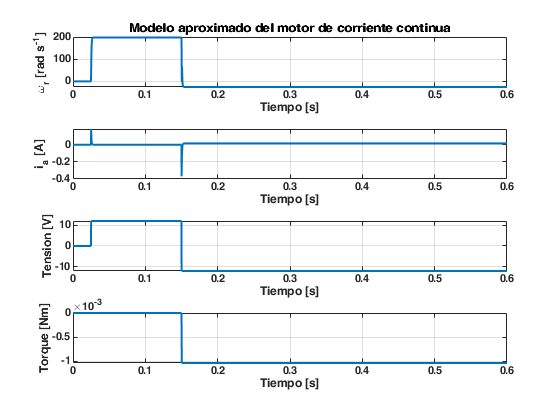

subplot(4,1,1)
plot(t,omega,'LineWidth',1.5)
ylabel('\omega_r [rad s^{-1}]');
xlabel('Tiempo [s]');
xlim([0 0.6])
title('Modelo aproximado del motor de corriente continua')
grid
subplot(4,1,2)
plot(t,current,'LineWidth',1.5)
xlabel('Tiempo [s]')
ylabel('i_a [A]')
xlim([0 0.6])
grid
subplot(4,1,3)
plot(t,va,'LineWidth',1.5)
xlabel('Tiempo [s]')
ylabel('Tension [V]')
xlim([0 0.6])
grid
subplot(4,1,4)
plot(t,tL,'LineWidth',1.5)
xlabel('Tiempo [s]')
ylabel('Torque [Nm]')
xlim([0 0.6])
grid

Se procede ahora a diseñar el controlador PID en base al requerimiento de que el sistema alcance una referencia de $\theta =1\;\mathrm{rad}$. Para ello, se implementa una integración con método de Euler en un controlador discreto. La consigna sugiere comenzar con los siguientes valores de las constantes involucradas:

- 
$$K_P =0\ldotp 1$$


- 
$$K_i =0\ldotp 01$$


- 
$$K_D =5$$


Para obtener el comportamiento del motor se crea una función, que está declarada en el bloque de código **motorModel.m**. Esto se hace porque en la bibliografía se planteó esa metodología, y termina siendo cómoda para ahorrar código en el Live Script.

El diagrama de bloques del sistema a implementar es el siguiente:

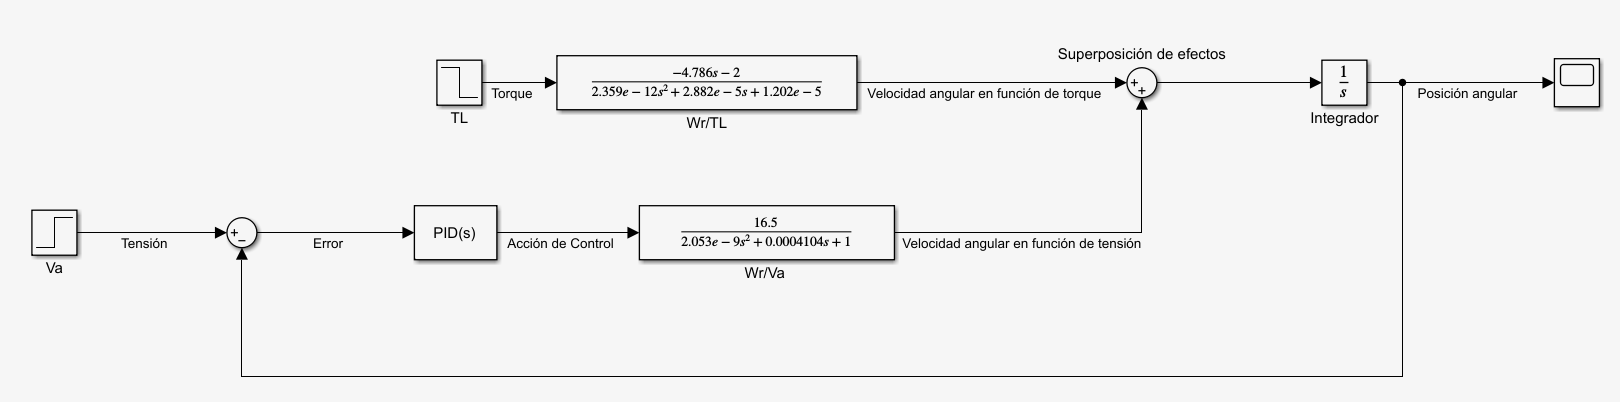

Continuando con el desarrollo, se declaran las variables necesarias a utilizar.

X = -[0; 0; 0];
index = 0;
h = 1e-7;
ref = 1;
simTime = 1e-3;
Kp = 0.1;
Ki = 0.01;
Kd = 5;
samplingPeriod = h;

Luego, las ecuaciones para el controlador PID.

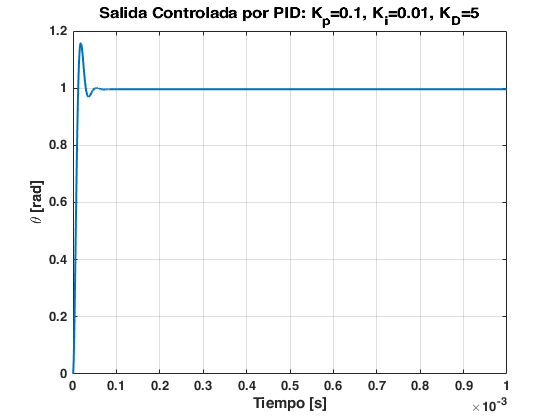

A = ((2*Kp*samplingPeriod)+(Ki*(samplingPeriod^2))+(2*Kd))/(2*samplingPeriod);
B = (-2*Kp*samplingPeriod+Ki*(samplingPeriod^2)-4*Kd)/(2*samplingPeriod);
C = Kd/samplingPeriod;
e = zeros(simTime/h,1);
u = 0;
for t = 0:h:simTime
    index = index+1;
    k = index+2;
    X = motorModel(h,X,u);
    e(k) = ref-X(3);
    u = u+A*e(k)+B*e(k-1)+C*e(k-2);
    theta(index) = X(3);
end
t = 0:h:simTime;
plot(t,theta,'LineWidth',1.5)
title('Salida Controlada por PID: K_p=0.1, K_i=0.01, K_D=5')
xlabel('Tiempo [s]')
ylabel('\theta [rad]')
grid

Puede comprobarse que hay un sobrepaso en la salida del sistema. Para eliminar ese pico se disminuye un poco en magnitud el valor de la acción derivativa, además se colocan sliders para mejorar la respuesta del sistema y acercarla más a la esperada. 

clear all;
X = -[0; 0; 0];
index = 0;
h = 1e-7;
ref = 1;
simTime = 1e-3;
Kp = 0.9

Kp = 0.9000

Ki = 1.24

Ki = 1.2400

%Kd = 1.5;
Kd =1.2

Kd = 1.2000

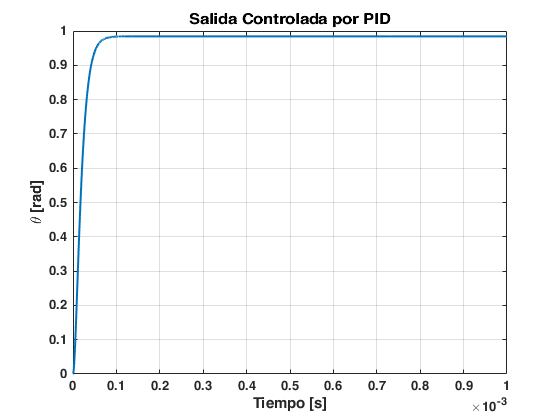

samplingPeriod = h;
A = ((2*Kp*samplingPeriod)+(Ki*(samplingPeriod^2))+(2*Kd))/(2*samplingPeriod);
B = (-2*Kp*samplingPeriod+Ki*(samplingPeriod^2)-4*Kd)/(2*samplingPeriod);
C = Kd/samplingPeriod;
e = zeros(simTime/h,1);
u = 0;
for t = 0:h:simTime
    index = index+1;
    k = index+2;
    X = motorModel(h,X,u);
    e(k) = ref-X(3);
    u = u+A*e(k)+B*e(k-1)+C*e(k-2);
    theta(index) = X(3);
end
t = 0:h:simTime;
plot(t,theta,'LineWidth',1.5)
title('Salida Controlada por PID')
xlabel('Tiempo [s]')
ylabel('\theta [rad]')
grid

Luego de modificar los valores de las constantes con los sliders, se llega a un controlador que elimina el sobrepaso. Pero, en contraparte tiene un error en estado estable. Este error es:

error = 1-max(theta)

error = 0.0155

errorPercentaje = error*100

errorPercentaje = 1.5537

El error en estado estable es finalmente $e_{\mathrm{ss}} =1\ldotp 5537%$, para las constantes del controlador siguientes:

- 
$$K_P =0\ldotp 9$$


- 
$$K_i =1\ldotp 24$$


- 
$$K_D =1\ldotp 2$$
